# **Case 3 (Heterogeneous WITH NICHE INFORMATION)**

(Daniel Rojas, Sebastian Mejia, Jhon Smith, Andres Felipe)

% Region: Bello
% Parameters: mu_h, mu_m, gamma, z, beta_hm, beta_mh, r, C, v_h, v_m
pars = [0.00145, 0.3848,0.9776,5.9052,0.9628,0.8030,13.9406,0.0182,4.78e3,1.58e4];
% Temporal Domain
domain = [1, 61];  % From t=1 to t=100
% Set Initial conditions
initial_conditions = [80, 20, 800, 200, 0]; 
names = {'M_S','M_I','H_s','H_I','H_R','\mu_h','\mu_m','\gamma','z','\beta_{hm}','\beta_{mh}','r','c_m','\nu_h','\nu_m'}; % Factors names
out_names = {'S_m(t)','I_m(t)','S_h(t)','I_h(t)','R_h(t)','I^{ac}(t)','N_m(t)','N_h(t)'}; % Output Names
factors = [initial_conditions,pars];
% Ranges
rpars = [0 0.6;0 1;0.1 1; 0 30;0 1;0 1;0 100;0 2e3;0 1e2;0 1e2];
rconds = [80 80; 0 70; 800 800; 0 300; 0 0];
range = [rconds;rpars];
% Gsua Toolbox implementation
TU = gsua_dataprep('SIR1',range,'domain',domain,'out_names',out_names,'names',names);

Setting environment to work with user-defined function


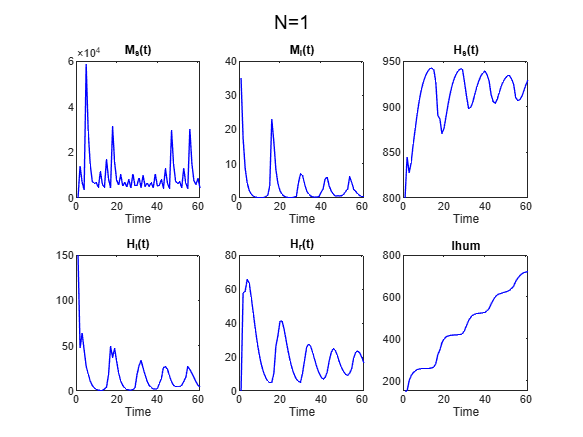

y=gsua_eval(TU.Nominal,TU);

TU.Properties.CustomProperties.output = 6;

# **Import data**

Below, we present the case 3 of the agent-based simulation.

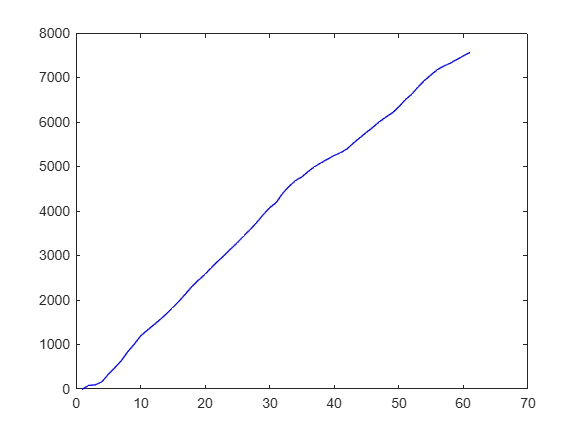

load NoUniformeA2_1.mat
close all

%Figure data Acumulative Infected Humans
xdata1=1:61;
dataY1=Hi(xdata1);
plot(dataY1,color='blue');

M=gsua_dmatrix(TU,7000); %Set of parameters of TU samples
TU

TU = 12x2 table
                  Range       Nominal
               ___________    _______

    M_I          0      70       35  
    H_I          0     300      150  
    mu_h         0     0.6      0.3  
    mu_m         0       1      0.5  
    gamma      0.1       1     0.55  
    z            0      30       15  
    beta_hm      0       1      0.5  
    beta_mh      0       1      0.5  
    r            0     100       50  
    C            0    2000     1000  
    v_h          0     100       50  
    v_m          0     100       50  


# **Sensitivity analysis**

[TU,J,Y]=gsua_sa(M,TU,'SensMethod','Xiao');

Progress: 8%
Estimated processing time (h:m:s): 0:0:9
Remaining time (h:m:s): 0:0:8
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 22:51:6
Number of simulations: 49000
Progress: 15%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:7
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 22:51:6
Number of simulations: 49000
Progress: 22%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:6
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 22:51:6
Number of simulations: 49000
Progress: 29%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:6
Elapsed time (h:m:s): 0:0:2
Estimated stop time (h:m:s): 22:51:5
Number of simulations: 49000
Progress: 36%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:5
Elapsed time (h:m:s): 0:0:3
Estimated stop time (h:m:s): 22:51:5
Number of simulations: 49000
Progress: 43%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:5
Elapsed time (h:m:s):

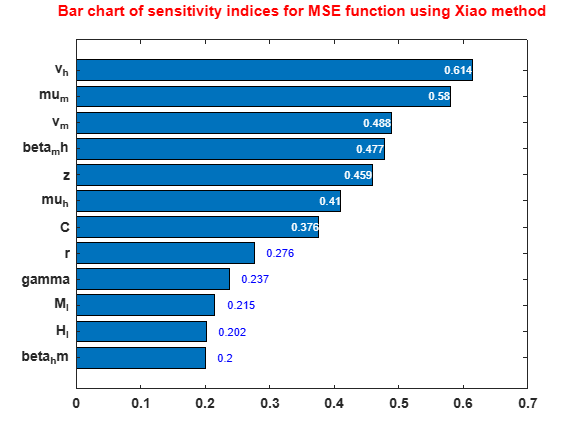

TU.Si;
sum(TU.Si);
sum(TU.STi);
clf
gsua_plot('Bar',TU,TU.STi)
colormap jet

# **Uncertainty analysis**

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 0:49:44
Number of simulations: 1000


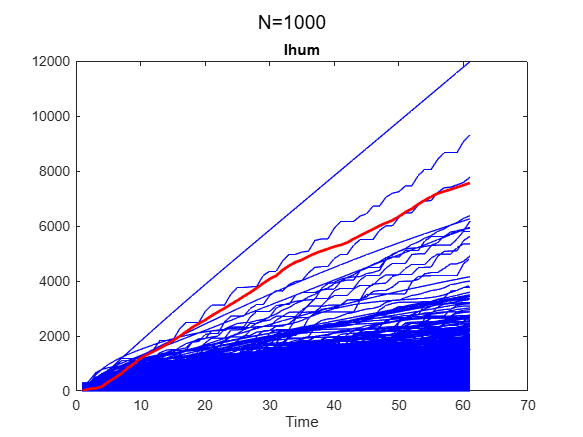

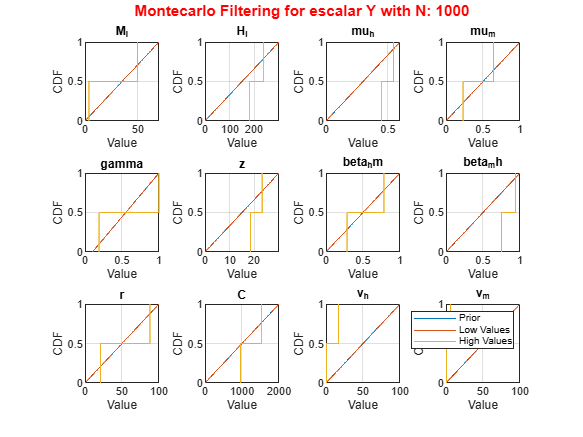

close all
gsua_ua(M,TU,'xdata',xdata1,'parallel',false,'ynom',dataY1);

# **Time series (Mathematical indicator of ecological niche)**

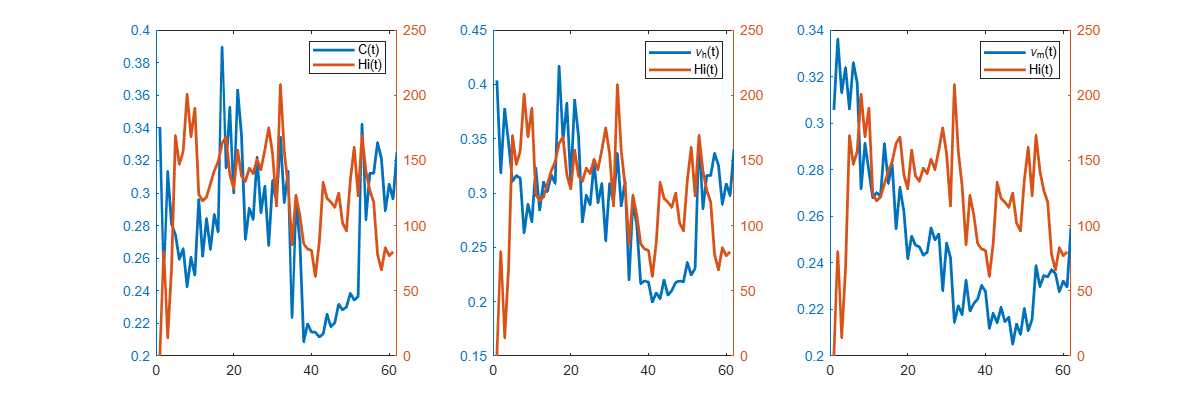

% Extraction of information from the maps
map1 = matrix_Map{1};%Information Home-Humans
map2 = matrix_Map{2};%Information Work Humans
map3 = matrix_Map{3};%Map Vector

H1 = map1(2:end, 3);%Map Home-Humans
H2 = map2(2:end, 3);%Map Work-Humans
V = map3(2:end, 3:end);%Map Vector
result_matrix = zeros(1, size(V, 2));
H = max([H1,H2],[],2);%Function max Map Work-Home
H_ponderador = H/sum(H); %Normalization of H 
V_ponderador = V./sum(V);%Normalization of V
nuH=sum(V.*H_ponderador);%Indicator for V_h(t)
nuM=sum(H.*V_ponderador);%Indicator for V_m(t)
Ct=mean(V(H~=0,:));%Indicator for Mosquito Carrying Capacity
Hi_noAcc=Hi-[0,Hi(1:end-1)];%Cases per week of dengue

%Figure Indicator for Mosquito Carrying Capacity, Indicator for V_m(t), Indicator for V_h(t) vs.
% Cases per week for dengue
figure('Position',[10 10 1200 400])
clf
subplot(1,3,1)
yyaxis left
plot(Ct,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"C(t)","Hi(t)"})
subplot(1,3,2)
yyaxis left
plot(nuH,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"\nu_h(t)","Hi(t)"})
subplot(1,3,3)
yyaxis left
plot(nuM,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"\nu_m(t)","Hi(t)"})

# **Link the time series to the model**

Prepare the structure to input the time series into the model

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 0:49:58
Number of simulations: 1000


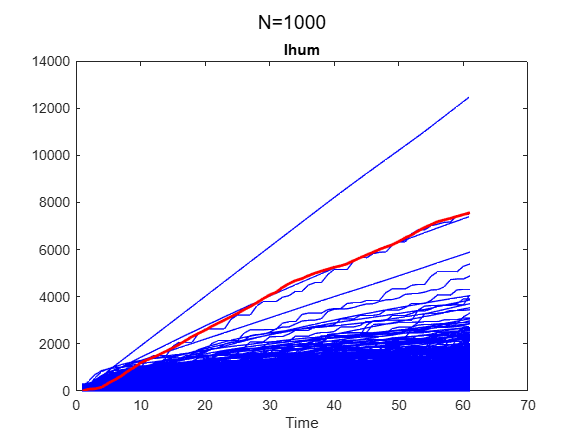

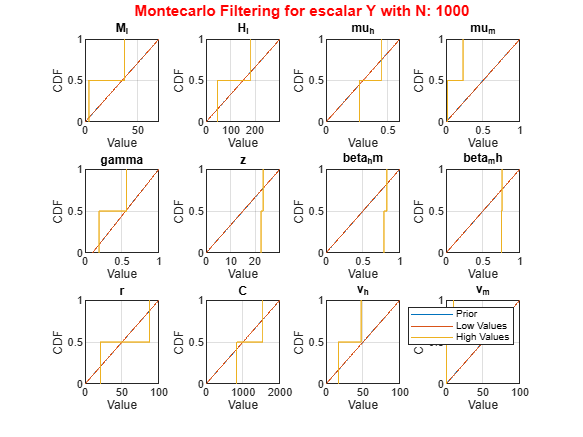

dataIn=struct();
dataIn.timeSer=Ct;
dataIn.Nuh=nuH;
dataIn.Num=nuM;
dataIn.action=2;

TU.Properties.CustomProperties.copt=dataIn;%The time series is assigned to the model
close all
gsua_ua(M,TU,'xdata',xdata1,'parallel',false,'ynom',dataY1);

# **Parameter estimation**

solver='fmincon';%this is the default solver
opt=optimoptions('fmincon','UseParallel',false,'MaxIterations',5e4,'MaxFunctionEvaluations',1e5);%configure optimizer
nestim=1000;
resT=zeros(1,nestim);
IPT=zeros(size(TU,1),nestim);
estimations=zeros(size(TU,1),nestim);

parfor i=1:nestim
    [T_e,res,IP] =gsua_pe(TU,xdata1,dataY1,'N',1,'solver',solver,'Show','off','opt',opt,'margin',0.3);
    IPT(:,i)=IP;
    resT(i)=res;
    estimations(:,i)=T_e.Estfmincon;
    clc
    if mod(i,30)==0
        disp("Progress "+num2str(round(nestim/i*100)))
    end
end

Generating a valid matrix for estimations
Estimation 1

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Progress: 100%
Estimated processing time (h:m:s): 0:0:7
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:7
Estimate


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1.000000e+05.

Progress: 100%
Estimated processing time (h:m:s): 0:1:17
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:1:17
Estimated stop time (h:m:s): 0:51:38
Number of simulations: 1
Generating a valid matrix for estimations
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the 


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Progress: 100%
Estimated processing time (h:m:s): 0:0:5
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:5
Estimated stop time (h:m:s): 0:58:9
Number of simulations: 1
Generating a valid matrix for estimations
Est


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1.000000e+05.

Progress: 100%
Estimated processing time (h:m:s): 0:1:16
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:1:16
Estimated stop time (h:m:s): 1:14:56
Number of simulations: 1
Generating a valid matrix for estimations
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the 


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1.000000e+05.

Progress: 100%
Estimated processing time (h:m:s): 0:1:14
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:1:14
Estimated stop time (h:m:s): 1:33:22
Number of simulations: 1
Generating a valid matrix for estimations
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the 

%[T_e,res,IP] =gsua_pe(TU,xdata1,dataY1,'N',nestim,'solver',solver,'Show','on','opt',opt,'margin',0.3);
[sortedResT,idx]=sort(resT,'ascend');
sortedEstims=estimations(:,idx);
IPT=IPT(:,idx);

save("ALEPHResultsEstims1000NUA2_SA.mat","sortedResT","sortedEstims","IPT");%SA stands for serie activa

# **Identifiability analysis**

clear;clc;close all

% Parameters: mu_h, mu_m, gamma, z, beta_hm, beta_mh, r, C, v_h, v_m
pars = [0.00145, 0.3848,0.9776,5.9052,0.9628,0.8030,13.9406,0.0182,4.78e3,1.58e4];
% Temporal Domain
domain = [1, 61];  % From t=1 to t=100
% Set Initial conditions
initial_conditions = [80, 20, 800, 200, 0]; 
names = {'M_S','M_I','H_s','H_I','H_R','\mu_h','\mu_m','\gamma','z','\beta_{hm}','\beta_{mh}','r','c_m','\nu_h','\nu_m'}; % Factors names
out_names = {'S_m(t)','I_m(t)','S_h(t)','I_h(t)','R_h(t)','I^{ac}(t)','N_m(t)','N_h(t)'}; % Output Names
factors = [initial_conditions,pars];
% Ranges
rpars = [0 0.6;0 1;0.1 1; 0 30;0 1;0 1;0 100;0 2e3;0 1e2;0 1e2];
rconds = [80 80; 0 70; 800 800; 0 300; 0 0];
range = [rconds;rpars];
% Gsua Toolbox implementation
TU = gsua_dataprep('SIR1',range,'domain',domain,'out_names',out_names,'names',names);

Setting environment to work with user-defined function


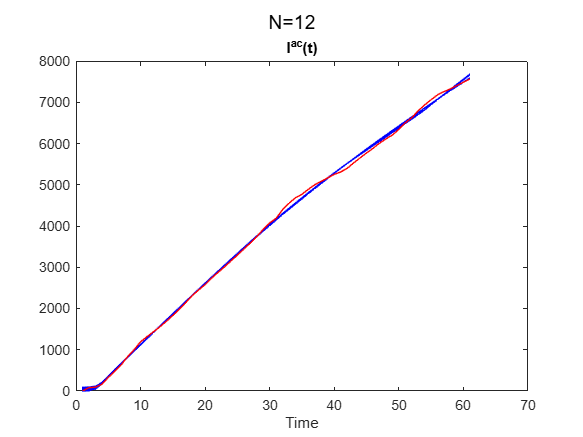

load ALEPHResultsEstims1000NUA2_SA.mat
load NoUniformeA2_1.mat

map1 = matrix_Map{1};%Information Home-Humans
map2 = matrix_Map{2};%Information Work Humans
map3 = matrix_Map{3};%Map Vector

H1 = map1(2:end, 3);%Map Home-Humans
H2 = map2(2:end, 3);%Map Work-Humans
V = map3(2:end, 3:end);%Map Vector
result_matrix = zeros(1, size(V, 2));
H = max([H1,H2],[],2);%Function max Map Work-Home
H_ponderador = H/sum(H); %Normalization of H 
V_ponderador = V./sum(V);%Normalization of V
nuH=sum(V.*H_ponderador);%Indicator for V_h(t)
nuM=sum(H.*V_ponderador);%Indicator for V_m(t)
Ct=mean(V(H~=0,:));%Indicator for Mosquito Carrying Capacity
Hi_noAcc=Hi-[0,Hi(1:end-1)];%Cases per week of dengue

figure('Position',[10 10 1200 400])
clf
subplot(1,3,1)
yyaxis left
plot(Ct,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"C(t)","Hi(t)"})
subplot(1,3,2)
yyaxis left
plot(nuH,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"\nu_h(t)","Hi(t)"})
subplot(1,3,3)
yyaxis left
plot(nuM,'LineWidth',2)
yyaxis right
plot(Hi_noAcc,'LineWidth',2)
legend({"\nu_m(t)","Hi(t)"})

dataIn=struct();
dataIn.timeSer=Ct;
dataIn.Nuh=nuH;
dataIn.Num=nuM;
dataIn.action=2;

TU.Properties.CustomProperties.copt=dataIn;%The time series is assigned to the model
TU.Properties.CustomProperties.output = 6;

xdata1=1:61;
dataY1=Hi(xdata1);
thr=min(sortedResT)*1.36;
TU.Estims=sortedEstims;
close all
selector=sum(sortedResT<thr);
figure(1)
y1=gsua_eval(TU.Estims(:,1:selector),TU,xdata1,dataY1);

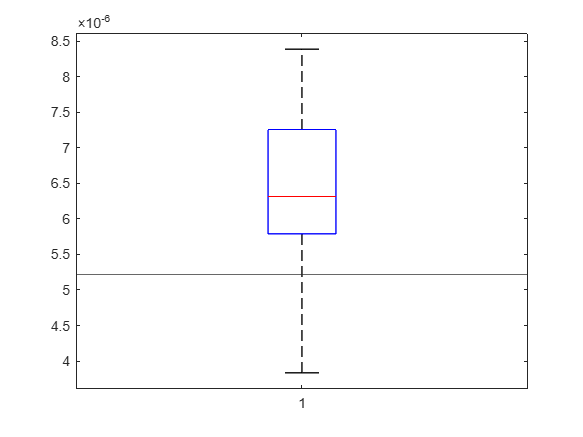

figure(2)
clf
boxplot(sortedResT(1:200))
hold on
yline(thr)

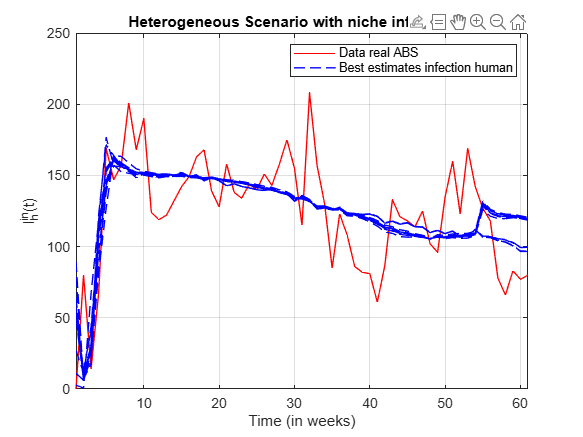

Hi1=Hi-[0 Hi(1:end-1)];
close all, figure(2), plot(Hi1,Color="r")
hold on
y=y1-[zeros(12,1) y1(:,1:end-1)];
plot(y','--',LineWidth=1,color="b");
grid on;

legend('Data real ABS','Best estimates infection human')
title("Heterogeneous Scenario with niche information")
xlabel("Time (in weeks)")
ylabel("I_{h}^{in}(t)")
xlim([1 61])

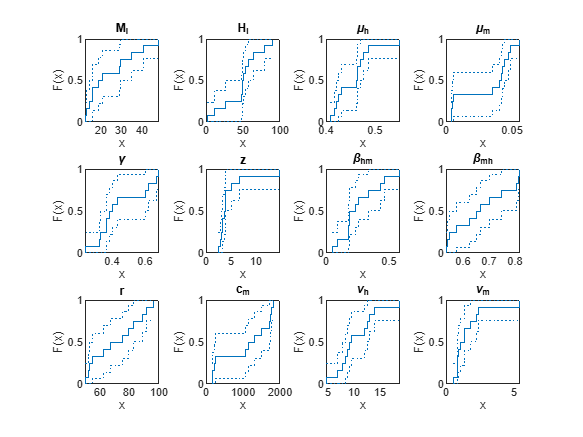

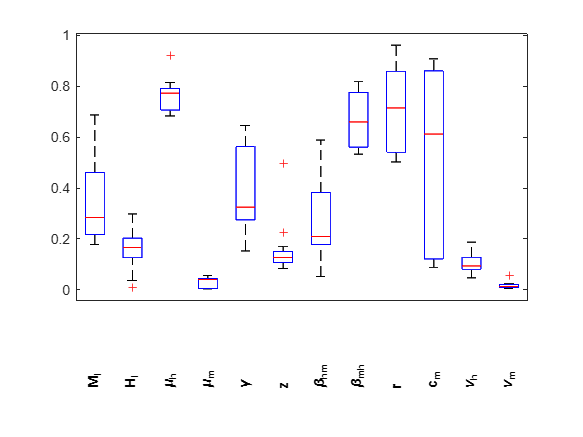

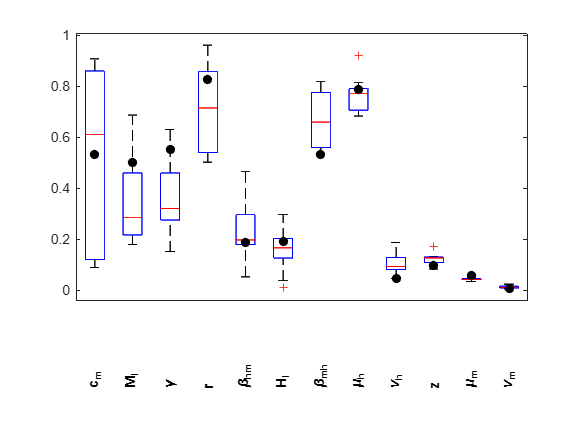

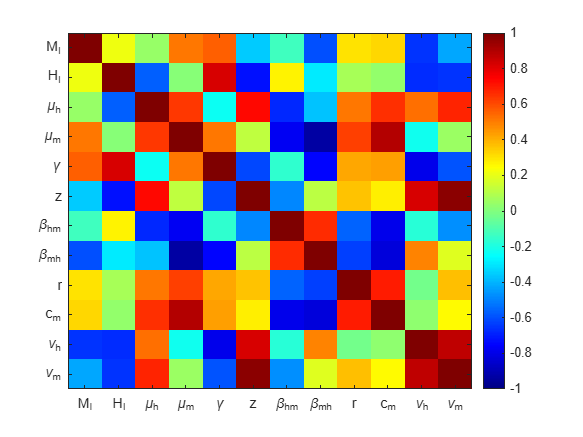

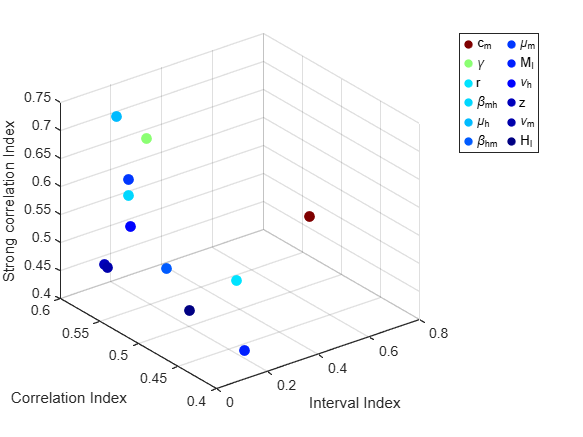

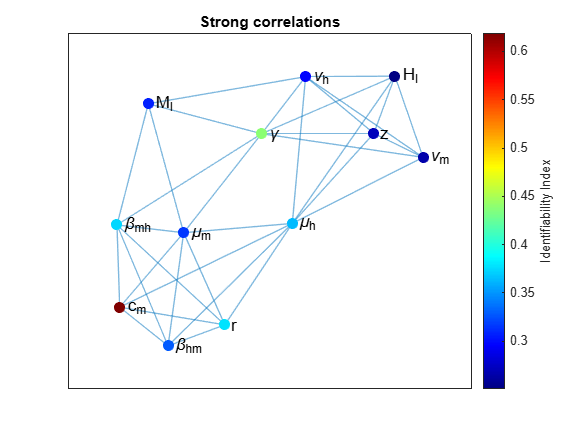

T = 12x5 table
                          Range             Nominal        Estims                                                                                  Est                                                                               index 
                  ______________________    ________    _____________    _______________________________________________________________________________________________________________________________________________________    _______

    M_I              15.905       29.392      19.895    1x1000 double       35.04       48.102       29.392       40.448       14.423       18.786       21.003        12.49       15.905       28.865       16.037       13.145    0.30723
    H_I              48.561       57.309      49.813    1x1000 double   

close all
Tia=gsua_ia(TU,TU.Estims(:,1:selector),true,false,true);

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 13:32:40
Number of simulations: 1000


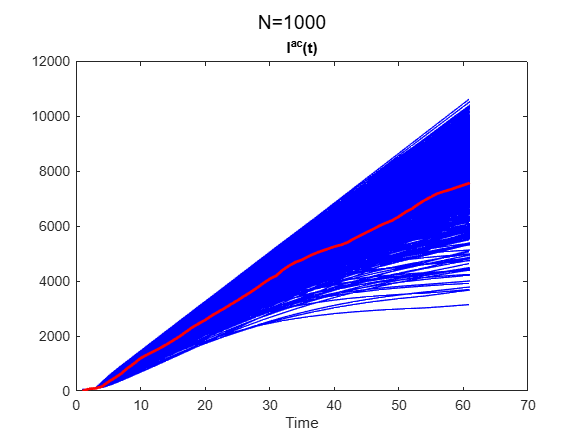

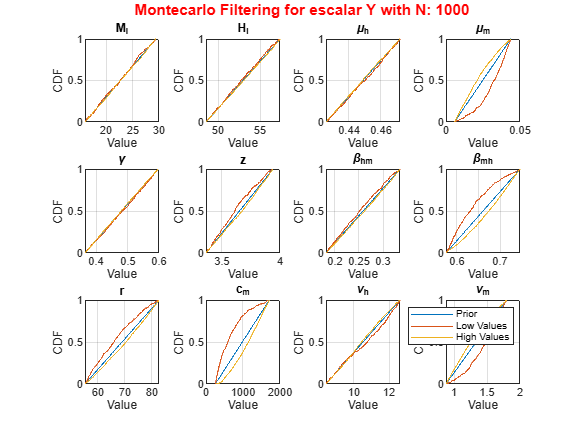

close all
Mia=gsua_dmatrix(Tia,1e3);
gsua_ua(Mia,TU,'xdata',xdata1,'parallel',false,'ynom',dataY1);

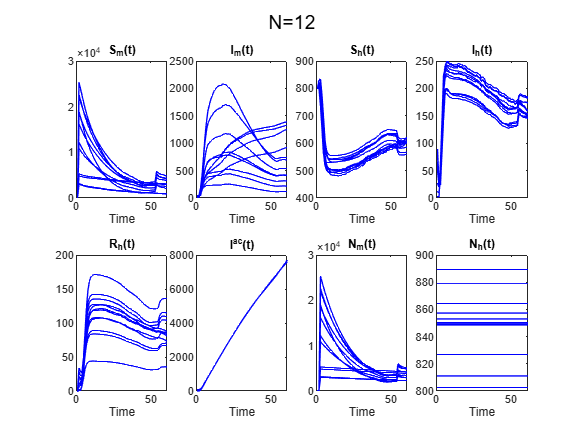

close all
TU.Properties.CustomProperties.output=1:8;
gsua_eval(TU.Estims(:,1:selector),TU,xdata1);

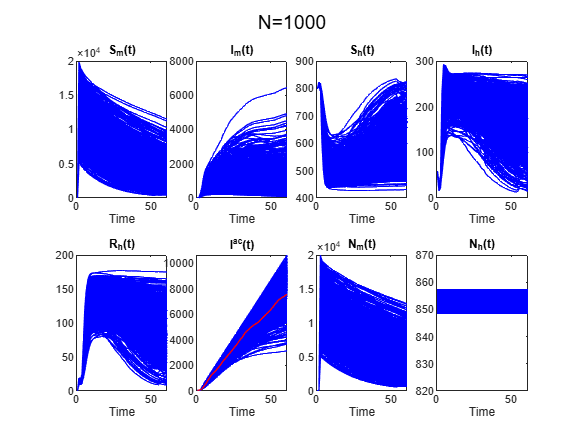

gsua_eval(Mia', TU, xdata1);
TU.Properties.CustomProperties.output = 1:8;

% Get the active figure
fig = gcf; 

% Find all axes in the figure
ax = findobj(fig, 'Type', 'Axes'); 

% Select the axis of the sixth subplot (adjust if the order is different)
ax6 = ax(4); 

% Activate the sixth plot axis and overlay the red curve
hold(ax6, 'on'); 
plot(ax6, xdata1, Hi(xdata1), 'r', 'LineWidth', 1);
hold(ax6, 'off');

% Select the axis of the eighth subplot (adjust if the order is different)
ax8 = ax(1); 

% Set the Y-axis limits in the eighth subplot
ylim(ax8, [820, 870]); % Replace y_min and y_max with the desired values